In this exercise you will plot and compare the hydraulic resistance of a rectangular cross section channel for different approximative expressions. The exact analytical solution for the hydraulic resistance in a rectangular cross-section channel involves computing an infinite sum. If no plots are shown press the green arrow (Run) or press F5 on your keyboard. To the right you can click Output inline to show plots in the code. Follow the instructions to add more plots and answer the questions.

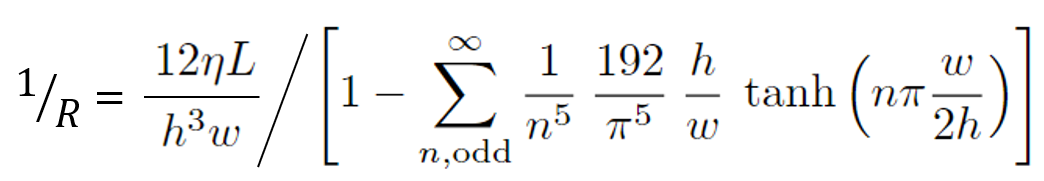

This sum converges nicely already after a few terms but it is still very tedious to compute without a computer. At the end of the code you can take a look at the function **exactRectangularResistance(eta,L,w,h)** that can be called in this script.

First we set the values of some parameters:

clear;                              % Clear all variables
close all;                          % close all open figures

L = 5e-2;                           % Set the channel length to be 5 cm 
w = linspace(100,10000,1000)*1e-6;  % Set the channel width to range from 100 µm to 10 mm
h= 100e-6;                          % Set the channel height to 100 µm
eta = 1e-3;                         % Set the dynamic viscosity to 1 mPas

## Exact form for rectangular cross-section channel

First we will compute the resistance for the exact solution using the function that was introduced above.

Rexact = exactRectangularResistance(eta,L,w,h);                                 % Compute the exact solution using the function at the end of this script

Now lets plot Rexact as a function of the aspect ratio (***h/w***) of the channel. 

figure(1)                                                                       % Create a new figure
plot(h./w,Rexact,'linewidth',2,'Displayname','Exact solution for a rectangle')  % Plot the exact solution
hold on                                                                         % Enable multiple plots in the same figure
xlabel('ratio h/w')
ylabel('Flow resistance [Pas/m^3]')
hLeg = legend('-Dynamiclegend');
set(hLeg,'Location','northwest');

The ratio ***h/w*** decreases with increasing ***w,**** so the channel is wide and shallow for low aspect ratios. For ***h/w*** = 1 the channel is a perfect square. The resistance increases as the aspct ratio increases due to the smaller cross section. *

## Rectangular approximate form

Now let's look in the formula sheet and find the expression for approximating the hydraulic resistance for a rectangular geometry.

RapproxRect = 12*eta*L./(h.^3*w.*(1-0.63*h./w));                % Compute the approximate rectangle solution using the function at the end of this script
figure(1)
plot(h./w,RapproxRect,'Displayname','Rectangle approximation')

Now we want to calcualte the relative error when using this approximaion. We subtract the approximation for R from th exact solution and then we divide by the exact solition in order to normalize. Then we convert to percentage and plot it.

figure(2)                                                                               % Make a new figure
eNormApproxRect =(RapproxRect-Rexact)./Rexact*100;                      % Calculate the normalized error in the hydraulic resistance
plot(h./w,eNormApproxRect,'Displayname','Rectangle approximation')      % Plot the normalized hydraulic resistance error as a function of h/w
hold on                                                                                 
xlabel('ratio h/w')                                                                     
ylabel('Relative error (%)')
hLeg2 = legend('-Dynamiclegend');
set(hLeg2,'Location','northwest');

From this plot we can see that this approximation is really good for a rectangle of low aspect ratio but it starts to break down around **h/w **= 0.5 and ***for a square geometry it is actually pretty bad.***

**Now evaluate some other approximative expressions and see how well they describe the flow resistance.  **

## Arbitrary shape approximation

In the ***formula sheet*** there is a formula that can be used for any type of cross section. Find the expression and enter below. Then uncomment the three lines of code by removing the '%'-marks.

%Rarb = [write the expression here and uncomment the code]
% figure(1)
% plot(h./w,Rarb,'Displayname','Arbitrary shape approximation')

% figure(2)
% plot(h./w,(Rarb-Rexact)./Rexact*100,'Displayname','Arbitrary shape approximation')


## Parallel plate approximation

Now try to approximate the rectangular geometry using a parallel plate

% Rparall = [write the expression here and uncomment the code]
% figure(1)
% plot(h./w,Rparall,'Displayname','Parallel plate approximation')

**Why is the flow resistance lower for the parallel plate approximation than for the exact solution?**

% figure(2)
% plot(h./w,(Rparall-Rexact)./Rexact*100,'Displayname','Parallel plate approximation')

## Circle approximation

Use a circle to approximate. Set the diameter to be the average of the hight and with of the channel. 

% Rcirc = [write the expression here and uncomment the code]
% figure(1)
% plot(h./w,Rcirc,'Displayname','Circle approximation')

**Why is the resistance for the circle approximation higher than for the exact solution?**

% figure(2)
% plot(h./w,(Rcirc-Rexact)./Rexact*100,'Displayname','Circle approximation')


## Square approximation

Use a square approximation. Set the side length to be the average of the hight and with of the channel.

% Rsquare = [write the expression here and uncomment the code]
% figure(1)
% plot(h./w,Rsquare,'Displayname','Square approximation')

**When is the square approximation really good?**

% figure(2)
% plot(h./w,(Rsquare-Rexact)./Rexact*100,'Displayname','Square approximation')

## Function to calculate the exact resistance

function [Rexact] = exactRectangularResistance(eta,L,w,h)
N = 21;
n = 1:2:N;
A = zeros(size(h));

for i = 1 : numel(n)
    A = A + tanh(n(i)*pi*w/2./h)/n(i)^5;
end

B = (1 - 192*h./w/pi^5.*A);

Rexact = 12*eta*L./(h.^3.*w.*B);
end